# Exercise 3

## Transforming Sensor Data Between References Frames

### About This Exercise

Now that you have the sensor readings from the point of view of the sensor, the natrual next steo us to determine where they are relative to both the robot and some fixed global frame, called the inertial frame, that stays constant as the robot moves. You are already familiar with the pose of the robot with respect to this frame, and we can similarly define the pose of the sensor with respect to the robot frame.

**By the end of this exercise, you'll be able to: **

- **Create a function that transforms data from one frame to another.**

- **Test code and functions using a script.**

*Remember to connect with your peers and the course facilitator if you get stuck or need help working through any part of this exercise.*

### Translation and Rotation

For this section, you will follow the steps for building up a transformation matrix. The following schematic will be useful for keeping track of all of the trigonometic operations involved.

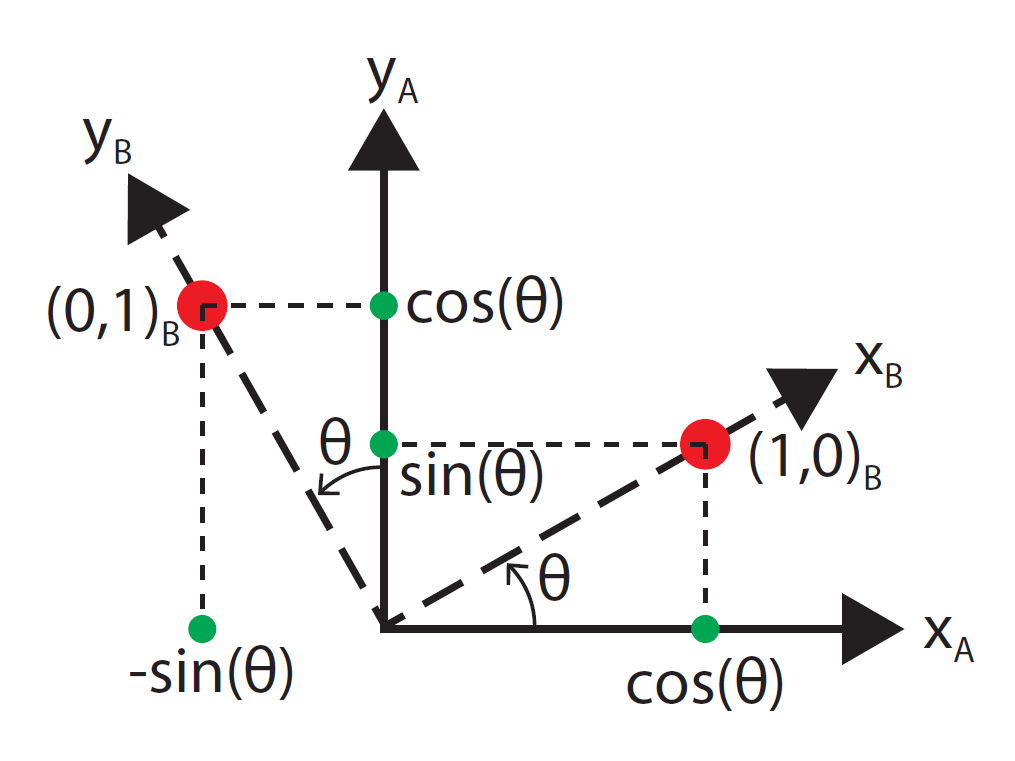

Let's start with a simple example where the orientation of the sensor matches the orientation of the robot. For this coordinate system, pose is reported as pose = [x_position y_position orientation]; Thus the pose of the sensor in the robot frame is defined by sensor_pose = [x_sensor y_sensor 0]. 

sensor_pose = [0.1, 0.1, 0]; 

**NOTE: **Throughout the MATLAB based exercises, pose is represented as a **row **vector. In the equations and videos on Cavas, pose is respresented as a **column** vector. Please keep this in mind, you will often need to transpose the pose in the equations in the MATLAB exercises. 

Here is an example data point (x,y) in the sensor frame:

dataxy_sensor = [0.3, 0.4];

Now, **complete code below **(and uncomment dataxy_robot) to set calculate the data in the robot frame. Remember you can index vectors like sensor_pose(1:2) to retrieve the first two elements. If you've used Python, indexing is a bit different as it starts at 1 instead of 0 and includes the final index.

%dataxy_robot = 

The following function will plot the data point in both the sensor frame and the robot frame. The sensor is shown as a blue square with an arrow indicating the positive x direction. The robot is a black circle with a radius pointing in its positive x direction. If you've implemented the above line correctly, the two plots should look the same, just shifted. Remember you can use the **Run Section** button above (or press Ctrl+Enter) to run this section of the script.

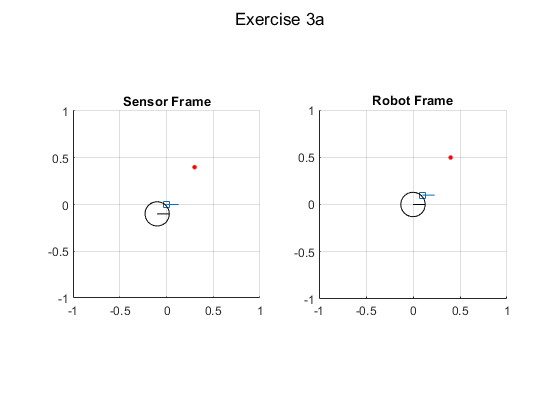

plot_title = "Exercise 3a"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

#### Rotating sensor data

The previous pose would be somewhat strange for a sensor, it is off to the corner of the robot but still looking forward. What if we were to rotate it by 45 degrees, or pi/4 radians, to look off diagonally towards the front left of the robot?

sensor_pose = [0.1, 0.1, pi/4];

Let's construct the rotation matrix first. To do so, we can ask what the x,y points in the robot frame are for the points [1, 0] and [0, 1] in the sensor frame separately, then combine them into one matrix. Refer to the figure from earlier to help you think this through. You will need to use sensor_pose(3).

Once the data is rotated, you should translate it as we did above using the x and y components of the sensor pose. 

**Complete the code below and uncomment dataxy_robot .**

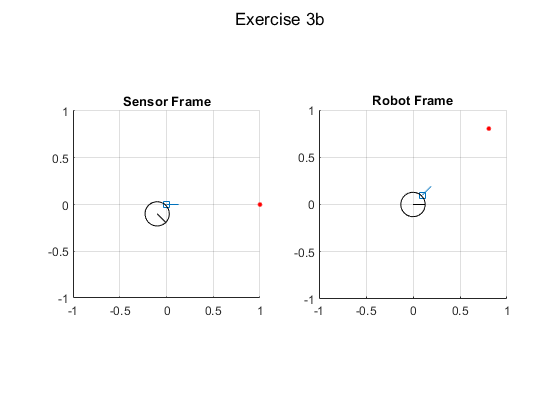

dataxy_sensor = [1, 0];
theta = sensor_pose(3); 
%dataxy_robot = 
plot_title = "Exercise 3b"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

Do the same for the point [0,1], using the figure above as a guide. Make sure the generated plots show the data in the same relative position to the sensor and robot in both frames.

**Complete the code below and uncomment dataxy_robot .**

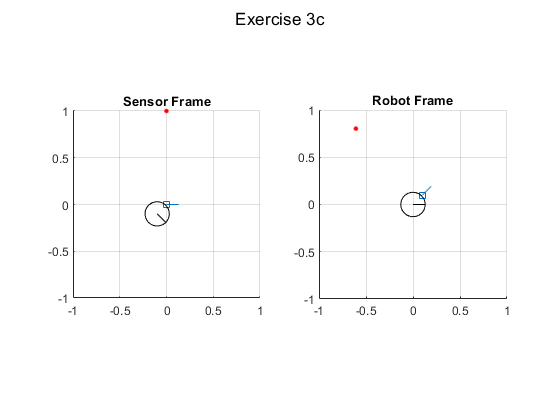

dataxy_sensor = [0 1];
%dataxy_robot =  
plot_title = "Exercise 3c"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

#### Rotation Matrix

Now you can assemble the above relations into a single matrix. The first column corresponds to the operations for point [1, 0], and the second corresponds to the operations for point [0, 1] as shown here:


$$Rot = \left[\matrix{cos(\theta) & -sin(\theta) \cr sin(\theta) & cos(\theta} \right]$$


**Complete the code below and uncomment rotation_matrix.**

%rotation_matrix =  

Let's test your matrix with a sample point. Run this section after completing the matrix above:

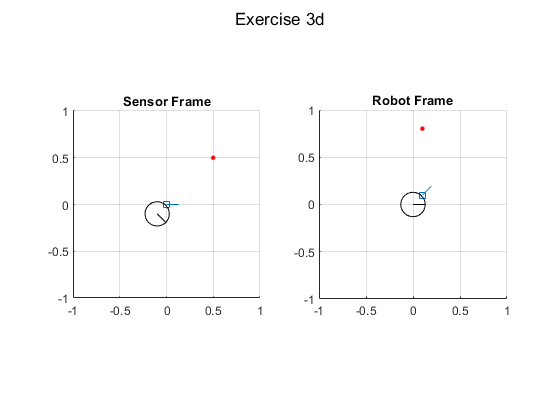

dataxy_sensor = [0.5 0.5];
dataxy_robot = rotation_matrix*dataxy_sensor'; %The second must be a column vector, so we transpose
dataxy_robot = dataxy_robot'; %Need to transpose back
dataxy_robot = dataxy_robot + sensor_pose(1:2);
plot_title = "Exercise 3d"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

Confirm your result by testing a second point. Run this section to see the result:

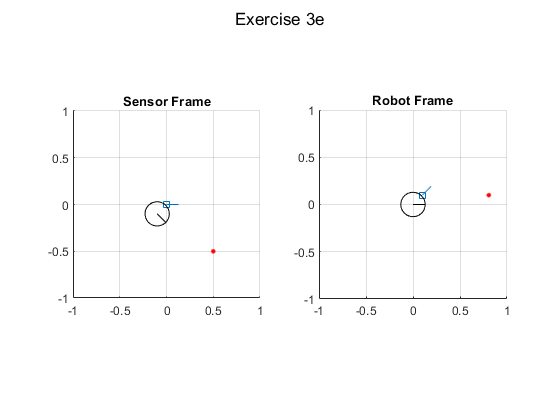

dataxy_sensor = [0.5 -0.5];
dataxy_robot = rotation_matrix*dataxy_sensor';
dataxy_robot = dataxy_robot'; 
dataxy_robot = dataxy_robot + sensor_pose(1:2);
plot_title = "Exercise 3e"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

Do your results make sense? 

#### Transformation Matrix

The translation operations can be added to the rotation matrix to create a transformation matrix that does operations for both x and y components in one step instead of the two above. If you add a third column with the x and y positions of the sensor with respect to the robot, they will be added appropriately if you append the number 1 to the end of the data vector. 


$$\left[ \matrix{x_{data}^r \cr y_{data}^r} \right] = \left[\matrix{cos(\theta) & -sin(\theta) & x_{sensor} \cr sin(\theta) & cos(\theta) & y_{sensor}} \right] * \left[ \matrix{x_{data}^s \cr y_{data}^s \cr 1} \right]$$


**Complete the code below and uncomment transformation_matrix .**

%transformation_matrix = 

Test with the a test point. This graph should be identical to the Exercise 3d plot. 

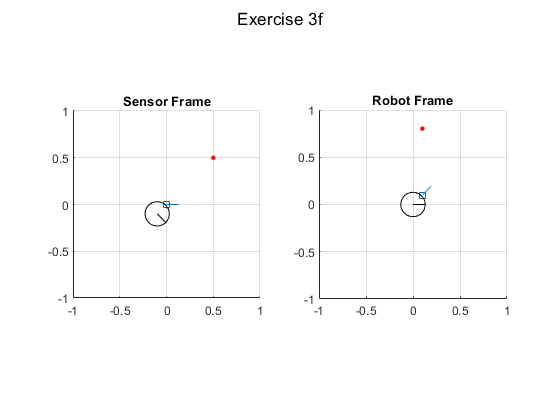

dataxy_sensor = [0.5 0.5];
dataxy_robot = transformation_matrix*[dataxy_sensor 1]';
dataxy_robot = dataxy_robot'; 
plot_title = "Exercise 3f"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

Another test point to confirm. This graph should be identical to Exercise 3e plot. 

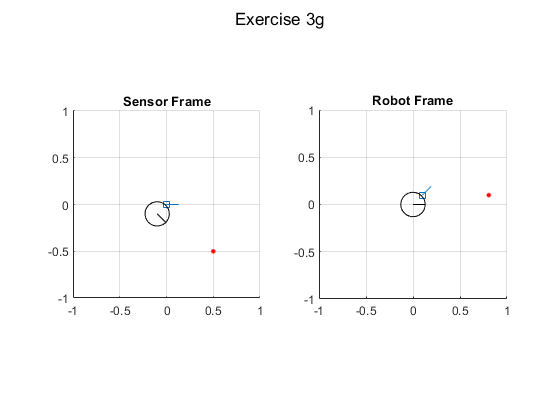

dataxy_sensor = [0.5 -0.5];
dataxy_robot = transformation_matrix*[dataxy_sensor 1]';
dataxy_robot = dataxy_robot'; 
plot_title = "Exercise 3g"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

#### True Transformation Matrix

It is useful for transformation matrices to be invertible, so you can use the matrix to go back and forth between frames. Thus you need a square matrix, so add the row [0 0 1] to your transformation matrix and append the number one to the data vector (which will always remain one after transformation and doesn't mean anything) as shown below:


$$\left[ \matrix{x_{data}^r \cr y_{data}^r \cr 1} \right] = \left[\matrix{cos(\theta) & -sin(\theta) & x_{sensor} \cr sin(\theta) & cos(\theta) & y_{sensor} \cr 0 & 0 & 1} \right] * \left[ \matrix{x_{data}^s \cr y_{data}^s \cr 1} \right]$$


**Complete the code below and uncomment transofmration_square**

%transformation_matrix_square = 

Test. This graph should be identical to the Exercise 3d and 3f plot. 

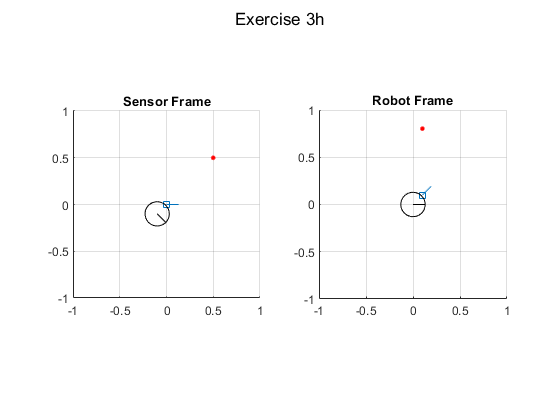

dataxy_sensor = [0.5 0.5];
temp = transformation_matrix_square*[dataxy_sensor 1]';
dataxy_robot = temp(1:2); % Only need the first two elements
dataxy_robot = dataxy_robot'; 
plot_title = "Exercise 3h"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

Let's see if the inverse works. The "\" operator inverts the first matrix and multiplies the second. Running the code below will plot a green circle of the data that has been transformed back into the sensor frame, and it should overlay with the original red dot.

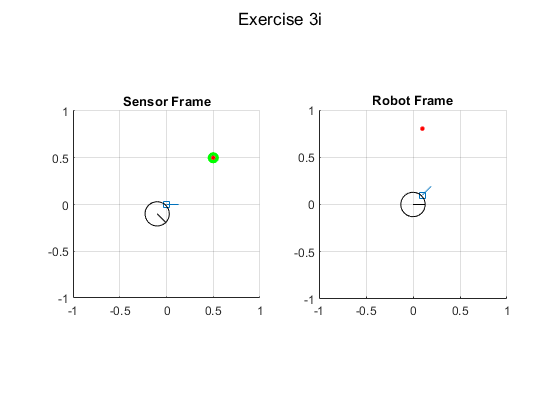

temp = transformation_matrix_square\[dataxy_robot';1]; 
data_sensor_redux = temp(1:2);

subplot(1,2,1)
plot(data_sensor_redux(1),data_sensor_redux(2),'og',"LineWidth",2.5)
plot_title = "Exercise 3i"; 
sgtitle(plot_title);

### Transformation Functions

Since you will be transforming data from one frame to another quite often, let's create a function that will perform the transofrmation. 

[► Complete the transform_points function](matlab:open('./transform_points.mlx')).

You can then use the code below to test your functions. Feel free to change the sensor_pose or the dataxy_sensor.

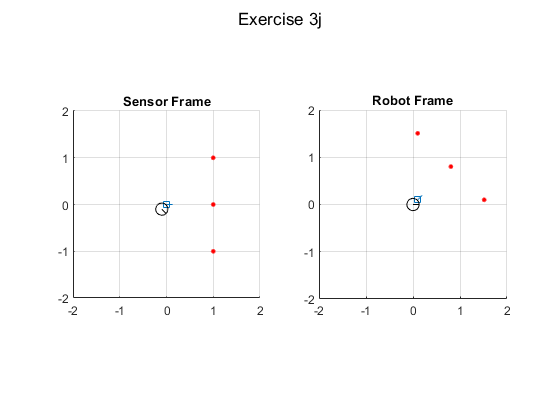

sensor_pose = [0.1 0.1 pi/4];
dataxy_sensor = [1, 0; 1, 1; 1, -1];
dataxy_robot = transform_points(sensor_pose, dataxy_sensor);
plot_title = "Exercise 3j"; 
plot_frames(sensor_pose, dataxy_sensor, dataxy_robot, plot_title);

### Finished!

These functions are general in that they can transform from any frame to another. So if you have the robot pose within the global frame and data in the frame of the robot, you can use the function to transform the data into the global frame. Similary, data in the global frame can be inversely transformed into the robot frame. You will be using these functions throughout the rest of this course, starting with the next exercise where you'll plot data collected from robot sensors into the global frame.